Investigate 15 MW turbine properties

load("bladedata_IEA_15MW.mat");

plot chord and twist

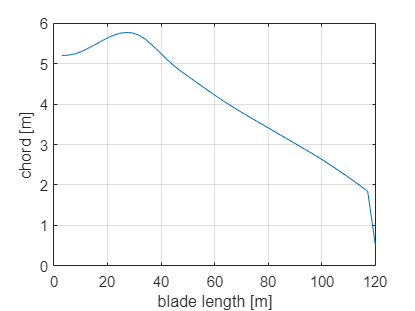

clf
plot(bladedata.radius,bladedata.chord)
xlabel("blade length [m]");
ylabel("chord [m]")
grid on

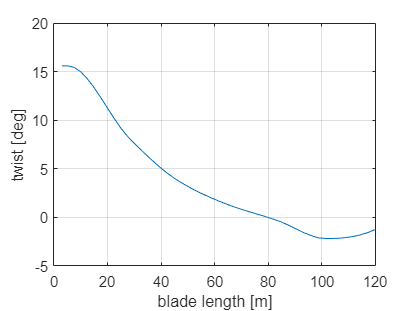


plot(bladedata.radius,bladedata.twist)
xlabel("blade length [m]");
ylabel("twist [deg]")
grid on

Lift and drag coefficents

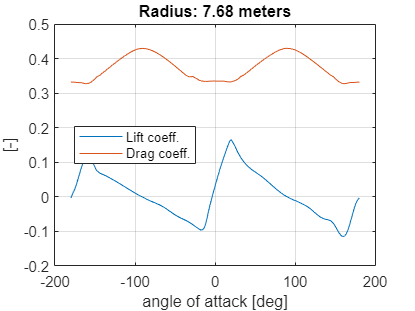

section=3;
clf
plot(bladedata.airfoil(:,1,section),bladedata.airfoil(:,2,section))
hold on
plot(bladedata.airfoil(:,1,section),bladedata.airfoil(:,3,section))
xlabel("angle of attack [deg]");
ylabel("[-]");
title(['Radius: ' num2str(bladedata.radius(section)) ' meters'])
legend(["Lift coeff.","Drag coeff."],Location="best");
grid on
hold off

Investigate 15 MW turbine steady state points

load("SS_IEA15MW.mat");

plot power curve and thrust curve, rotorspeed and bladepitch

clf
plot(SS.WINDSPEED,SS.POWER)
xlabel("wind speed [m/s]");
ylabel("power [MW]")
grid on

plot(SS.WINDSPEED,SS.THRUST*10^-3)
xlabel("wind speed [m/s]");
ylabel("thrust [kN]")
grid on

plot(SS.WINDSPEED,SS.ROTSPD)
xlabel("wind speed [m/s]");
ylabel("Rotor speed [RPM]")
grid on

plot(SS.WINDSPEED,SS.BLADEPITCH)
xlabel("wind speed [m/s]");
ylabel("Bladepitch [deg]")
grid on